clc;
clear;
syms x;

a = 1;
b = 0;
c =0

c = 0


%f(x) = 4 * x^2 - 2 * x - 4;
f =0;

P = 1; % Only works till P = 6  % Gauss points restriction
% P Order of Interpolation Function for element

% No of elements
e = 1;

% domain of X
x0 = 0;
xL = 1;

L = xL; % Length

[K_global_D_bc, Fv, S, X_nodes] = FEM_Processor(P, e, L, a, b, c, f);

% Get the handle of the command window
commandwindow;


% Prompt the user to input boundary conditions at x0
prompt_x0 = 'Enter the type of boundary condition at x0 (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        u0 = input('Enter the Dirichlet value u at x0: ');
    case 2
        Q0 = input('Enter the Neumann value AE*(du/dx) at x0: ');
    case 3
        K0 = input('Enter the spring constant K at x0: ');
        Del0 = input('Enter the spring displacement Del at x0: ');
    otherwise
        error('Invalid boundary condition type at x0');
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        uL = input('Enter the Dirichlet value u at xL: ');
    case 2
        P1 = input('Enter the Neumann value AE*(du/dx) at xL: ');
    case 3
        K1 = input('Enter the spring constant K at xL: ');
        Del1 = input('Enter the spring displacement Del at xL: ');
    otherwise
        error('Invalid boundary condition type at xL');
end


Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));


% For X0 left node we need to add correction factor
if exist('Q0', 'var') 
    Gv(1) = -Q0;   % Correction factor Added
end

if exist('K0', 'var') && exist('Del0', 'var')
    Sv(1) = -K0 * Del0;    % Correction factor Added
    K_global_D_bc(1, 1) = K_global_D_bc(1, 1) + K0;
end


if exist('P1', 'var') 
    Gv(end) = P1;
end

if exist('K1', 'var') && exist('Del1', 'var')
    Sv(end) = K1 * Del1;  
    K_global_D_bc(end, end) = K_global_D_bc(end, end) + K1;
end

RHS = Fv + Gv + Sv;


% Handle boundary conditions at x0
if exist('u0', 'var') 
    K_global_D_bc(1, :) = [1, zeros(1, S-1)];  % u0 = 0
    RHS(1) = u0;  % RHS of equation
end

% Handle boundary conditions at xL
if exist('uL', 'var') 
    K_global_D_bc(end, :) = [zeros(1, S-1), 1];  % uL = 0
    RHS(end) = uL;  % RHS of equation
end  

K_global_D_bc

K_global_D_bc =     11    -1
     0     1


RHS

$$RHS = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


u_nodes = double(K_global_D_bc \ RHS);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X_nodes, u_nodes, 'VariableNames', {'Nodal Location', 'u node value'});
disp(myTable);

    Nodal Location    u node value
    ______________    ____________

          0                0      
          1                0      



disp("-------------------------------------------------------------")

-------------------------------------------------------------



syms x  u_e(x)
%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

d_ue(x)= diff(u_e,x);


if exist('Q0', 'var') 
    ic0=d_ue(x0) == Q0;  

elseif exist('K0', 'var') && exist('Del0', 'var')
    ic0=d_ue(x0) == K0 * Del0;    
else
    ic0=u_e(x0) == u0;
end

if exist('P1', 'var') 
    icL=d_ue(xL) == P1;  

elseif exist('K1', 'var') && exist('Del1', 'var')
    icL=d_ue(xL) == K1 * Del1;    
else
    icL=u_e(xL) == uL;
end

u_exact = dsolve(deqn,[ic0 icL]);
exact_sol_f = u_exact

$$exact\_sol\_f = 0$$

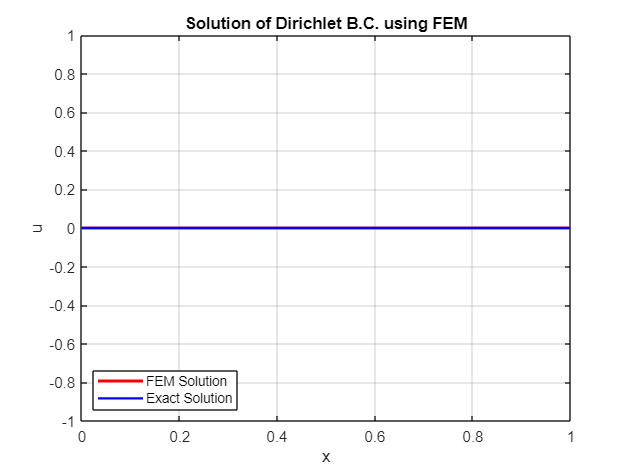

%----------------------------------------------------------------------------------


%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_nodes, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;